# Virtual Measurement of e/m

## Introduction

In one of the landmark experiments in physics near the end of the 19th century, J.J. Thomson measured the ratio of the charge to mass of the electron $e/m$. At this point in time, the electron was only postulated to explain electricity. Thomson showed that the electron does exist as a distinct particle with mass and charge and that it was much smaller the hydrogen ion H$^+$.  

In this virtual lab, you will replicate J.J. Thomson's experiment with a slightly modified apparatus and estimate the electron charge to mass ratio, $e/m$.

### **Background**

When charged particles are placed in electric ($\vec{E}$)  and magnetic fields ($\vec{B}$) they experience forces. The force exerted on a charge, $q$, by an electric field is 


$$\vec{F} = q\vec{E}, \qquad \qquad  (1)$$


whereas the force exerted on a charge by a magnetic field is 


$$\vec{F} = q\vec{v}\times \vec{B},  \qquad (2)$$


where $\vec{v}$ is the velocity of the charge. Charges must be moving in a magnetic field to feel a magnetic force. Here, $\times$ denotes the vector cross product of $\vec{v}$ and $\vec{B}$. Since this magnetic force is represented mathematically by a vector product, it leads to a unique type of motion for charged particles. 

For instance, if a charged particle moves with a velocity perpendicular to the magnetic field, the charge will move on a circular path as shown below. 

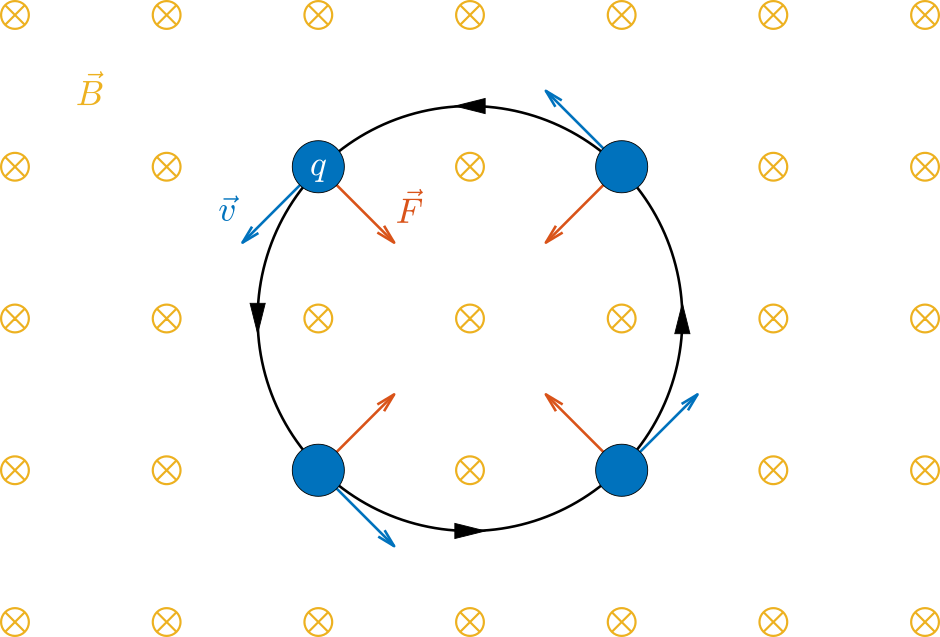

**Figure 1**. Charge $q$ moving in a magnetic field $\vec{B}$.

Here, the charge, $q$, is moving counter-clockwise through the magnetic field,$\vec{B}$, which is pointing into the screen. The magnetic force vector will always point toward the circle's center while the velocity vector points tangent to the circle. 

### Experiment Overview

Thomson's experiment uses the phenomenon described above to measure the electron's charge to mass ratio: $e/m$. Before entering the magnetic field, electrons are accelerated through a voltage and formed into a concentrated beam by an **electron emitter**. The speed of the electrons exiting the emitter depends on the potential difference, $V_e$, inside the electron emitter. Electrons accelerated through the field will gain kinetic energy ($E_k = \frac{1}{2}mv^2$) equal to the potential energy supplied by the emitter.

After being accelerated through the electron emitter, the electron beam is passed between two current-carrying coils, a device called a **Helmholtz Coil**, which produces a uniform magnetic field in the region between the coils (see **Fig. 2**). For a Helmholtz coil, the magnetic field near the center is related to the current passing through the coils by 


$$B = \left(\frac{8}{5\sqrt{5}} \right)\frac{N \mu_0 I}{r_c} \qquad \qquad (3)$$


where:

- $N$: number of turns in each coil 

- $\mu_0 = 4\pi\times10^{-7}$ T$\cdot$m/A: the permeability of free space

- $I$: current passing through the coils, in Amperes

- $r_c$: radius of the coils, in meters 

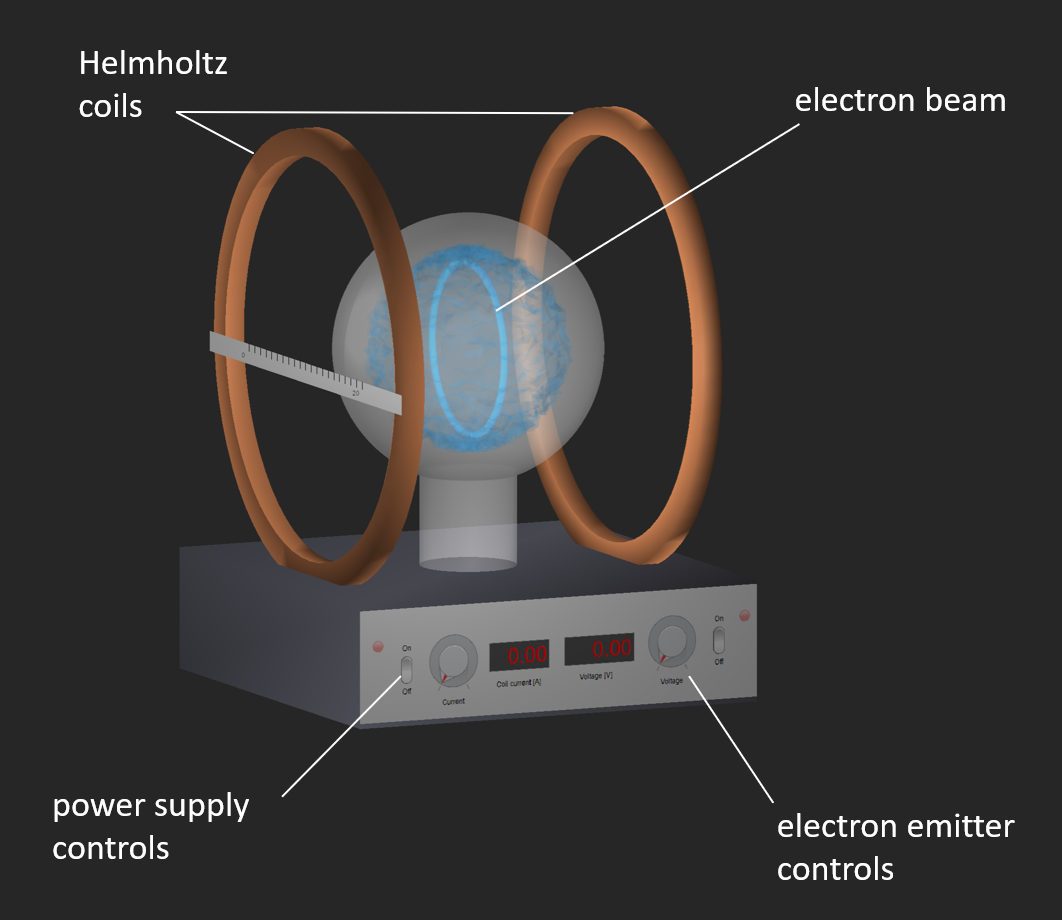

**Figure 2**. Experimental apparatus. This is a slightly modified version of the original apparatus used by J.J. Thomson.

The emitter is oriented so that the electrons travel in the direction perpendicular to the magnetic field. In a sufficiently strong magnetic field, this causes the beam to bend to a circular path. By measuring the radius of the path for a variety of magnetic field values, one can infer the charge to mass ratio, $e/m$, of the electrons.

### Pre-Lab Questions

**Question 1**. Before entering the magnetic field, the electrons are accelerated through a potential difference, $V_e$, inside the electron emitter.  Assuming that the electrons are initially at rest, use conservation of energy to determine their velocity, $v$, after being shot out of the emitter. Type your expression in the space provided below using the symbolic variables `e`, `V_e`, and `m`. 

**Solution:**


$$E_i = E_f$$



$$U_i = K_f + U_f$$



$$-\Delta U = K_f$$



$$eV_g = \frac{1}{2}mv^2$$


syms e V_e m
v_q1 = sqrt(2*e*V_e/m) % Replace NaN with your answer

**Hint**: The electrical potential energy change for a charge, $q$, passing through a potential difference, $V$, is $qV$.

**Question 2.** When the electrons are in the magnetic field, $B$, they move on a circular path that lies in the plane perpendicular to the magnetic field. The magnetic force propels the electrons in the direction perpendicular to their velocity vector (see **eq. (2) **and **Fig. 1**). Use the equation for the magnetic force and Newton's second law to determine an equation for the charge to mass ratio, $e/m$. Type your expression in the space provided below in terms of the symbolic variables` V_e`, `B`, and `R`.

**Solution:**


$$F_{\text{ net}} = m\frac{v^2}{R}$$



$$evB\sin\theta = m\frac{v^2}{R}$$



$$eB = m\frac{v}{R}$$



$$eB = \frac{m}{R}\sqrt{\frac{2eV_e}{m}}$$



$$e^2 B^2 = \frac{m^2}{R^2} \frac{2eV_e}{m}$$


syms B R
em_q2 = 2*V_e/( B^2 * R^2) % Replace NaN with your answer

**Hint**: The centripetal acceleration of an object with mass $m$ moving along a curve with radius $R$ is $a_c = v^2/R$.

**Question 3. ** The Helmholtz coil used in the virtual experiment below has a radius of 15 cm and contains 130 wire turns. If a current of 1 amp is applied to the coil, what will the strength of the magnetic field be near the center?

**Solution:**


$$B = \left(\frac{8}{5\sqrt{5}} \right)\frac{130 \cdot 4 \pi \times 10^{-7} \cdot 1}{0.15} = 7.79 \times 10^{-4}$$


N = 130;
mu0 = 4*pi*10^-7;
rc = 0.15;
B_q3 = (8/(5*sqrt(5)))*N*mu0*1/rc % Replace NaN with your answer

**Hint**: Unit conversions.

**Question 4.**

Suppose that the electron emitter voltage is set to $V_g=150$ V. At what speed $v$ will the electrons exit the emitter? Note: the accepted charge and mass of the electron are $e = 1.602\times10^{-19}$C and $m = 9.11\times10^{-31}$kg, respectively. Here "accepted" means the value accepted by the scientific community. 

**Solution:**

e = 1.602e-19;
m = 9.11e-31;
V_e = 150;
v_q4 = sqrt(2*e*V_e/m) 

**Question 5.**

If the electrons enter the magnetic field with a speed, $v$, in the direction perpendicular to the field, what is the radius of the circular path that they traverse through the field? Use the magnetic field strength, $B$, and electron velocity, $v$, that you calculated in questions 3 and 4, respectively. Give your answer in centimeters.

**Solution:**

m = 9.11e-31;
v = 7.26e6;
e = 1.602e-19;
B = 7.79e-4;

R_q5 = m*v/(e*B)*100 % Replace NaN with your answer

**Hint**: Use Newton's second law.

**Question 6**. What is the accepted value of the charge to mass ratio of an electron? 

**Solution:**

e = 1.602e-19;
m = 9.11e-31;
em_q6 = e/m % Replace NaN with your answer

**Hint**: Use the accepted values from **Question 4**.

## Virtual Experiment

In this virtual experiment, you'll take measurements from a slightly modified version of Thomson's apparatus. Afterward, you'll use these measurements to estimate the electron charge to mass ratio: $e/m$.

- Begin the experiment by clicking the link to run [emApparatus.mlapp](matlab: run("emApparatus.mlapp")) in MATLAB (to open the app using this link, it must be on your [MATLAB Search Path](https://www.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html)).

- Turn the power supply on and adjust the current passing through the Helmholtz coils to 1.75A. 

- Turn on the electron emitter and set the voltage to 200V.

- Hover over the apparatus, and the axes rotation icon will appear. Use the rotation widget to adjust the apparatus figure view so that you are looking at the ruler face-on, as shown in **Fig. 3**. 

- Use the ruler to take measurements and estimate the **radius** of the circular electron beam. You will need to measure the location of either side of the electron halo by clicking on the ruler. Your measurements will appear in the field labeled "Last ruler measurement." Compute the beam radius from your ruler measurements. 

- Record your current and radius measurements in the table.

- Repeat steps 5 and 6 for five additional values of the current passing through the Helmholtz coils. 

- After compiling at least six data points, export your data by clicking "Export Table to em_exp.mat," this will save your data to a MAT-file that you will load and process in the data analysis section below.

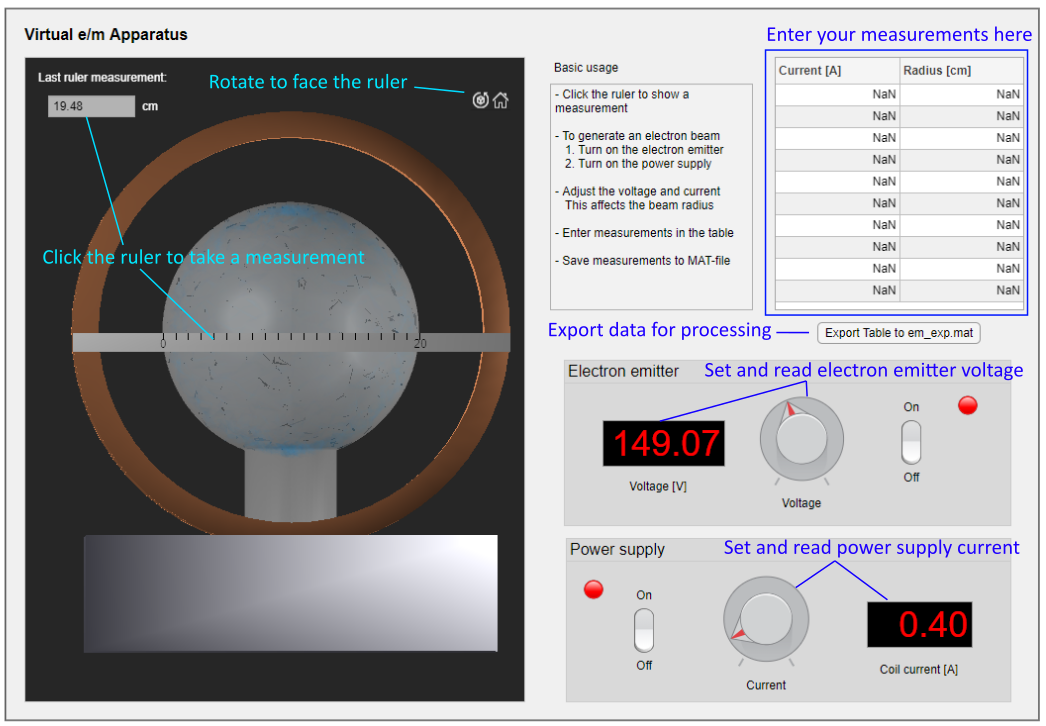

**Figure 3**. How to use the virtual experimental apparatus.

## Data Processing & Analysis 

### Part 1

In the prelab, you derived theoretical equations that relate $R$, $e/m$, and $B$. In this section, you'll use the virtual experiment data to estimate the electron charge to mass ratio, $e/m$, using those relationships. 

**Task 1. **Start by loading the measurements that were exported from the app. You can load data from a MAT file as

% write code here to load the data stored in em_exp.mat
load emExpSoln.mat % Note: normally this would read em_exp.mat
current_amp
radius_cm

Note that your current measurements are saved in an array `current_amp` and your radius measurements in `radius_cm`. The number of elements in these arrays corresponds to the number of measurements you took. All radius measurements are in centimeters.

**Task 2. **Start by converting the radii to meters in the space provided below and store the result in a new variable `R`.

R = radius_cm/100 % Replace NaN with your calculation that converts radius_cm to the radius in meters

**Task 3.**  Each current that you measured in the experiment generates a different magnetic field between the Helmholtz coils. Use equation (3) to compute the magnetic field strength for each of your experimental current readings. In the virtual experiment, the radius of the coils is 15 cm and the coils contain 130 turns.

% First, store the current readings in a variable I
I = current_amp % Set I to current_amp by replacing NaN
% Compute B using (3)
N = 130;
mu0 = 4*pi*10^-7;
rc = 0.15;
B = (8/(5*sqrt(5)))*N*mu0*current_amp/rc % Replace NaN with your expression for B

**Hint: **Use MATLAB expressions to compute all the magnetic field strengths simultaneously.

**Task 3. **Estimate $e/m$ for each value stored in `B` using the equation you derived in the prelab section that relates $e/m$ to $B$ and $R$. Note that you will need to use [dot-notation](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html) when performing division (`./`), multiplication (`.*`),  and powers (`.^`). The dot-notation is used to perform element-wise operations on arrays, like `B` and `I`.  

Ve = 200; % Replace NaN with the emitter voltage used in the experiment
em = 2*Ve./(B.^2 .* R.^2) % Replace NaN with your expression for e/m

**Task 4.**

Use the functions [`mean`](http://www.mathworks.com/help/matlab/ref/mean.html) and [`std`](http://www.mathworks.com/help/matlab/ref/std.html) to find the mean and standard deviation of your $e/m$ values. Store these in variables `mean_em` and `std_em`, respectively. 

mean_em = mean(em) % Replace NaN with a call to avg()
std_em = std(em) % Replace NaN with a call to std()

#### Questions

**Q1**. Is your estimated value for the electron charge to mass ratio consistent with the accepted value? Does the accepted value fall within one standard deviation of the mean? 

abs(mean_em-em_q6)
DAQ1Answer = "Yes, the absolute difference is 2.2e9, while the std dev is 7.3e9.";

**Q2.** What are some factors that could have introduced systematic error into the experiment? How would these have affected your results? What could have been done differently to mitigate these errors?

DAQ2Answer = "1. Systematic measurement noise introduced by whoever wrote the app. 2. Measurement errors caused by not looking at the ruler from the correct angle. You could check the app noise generator and ensure that the view angle is correct when taking measurements.";

### Part 2

It is often preferable to fit a function to data and use its fitted parameters to estimate a value, rather than average several estimated values. This method helps to identify misrecorded or outlier data and illustrate systematic errors. In this section, you will use this method with a linear function to estimate $e/m$.

**Task 1. **The relationship that you derived in **prelab Q2 **can be written as a linear relationship between the reciprocal square of the radius, $1/R^2$, and the square of the magnetic field strength, $B^2$. In other words, you can rearrange the relationship so that it is in the form

$\frac{1}{R^2} = \alpha B^2$.

Rewrite the relationship so that it is in the form shown and find the expression for $\alpha$. Type your answer in the space provided below in terms of the symbolic variables `e`, `m`, and `V_e`.

syms e m V_e
alpha_task1 = (e/m)*(1/(2*V_e)) % Replace NaN with your expression for alpha

**Task 2. **Define MATLAB variables for $1/R^2$ and $B^2$, using the radius measurements `R` and magnetic field strengths `B` that were computed in the last section. Don't forget to use `.^` and `./`, as  `B` and `R` are arrays.

reciprocalRSq = 1./R.^2 % Replace NaN with an expression for the reciprocal of R squared
Bsq = B.^2 % Replace NaN with the expression for B squared

**Task 3. **Create a scatter plot of your data using the MATLAB [`scatter`](http://www.mathworks.com/help/matlab/ref/scatter.html) function. Set `x` to $B^2$ and `y` to $1/R^2$. The slope of this line will be $\alpha$.

scatter(Bsq,reciprocalRSq)

**Task 4. **Next, find a line of best fit. This can be done using [`fit`](http://www.mathworks.com/help/curvefit/fit.html) with the syntax

Here, `x` and `y` are the data points and `fitType` should be set to `"poly1"` because you are looking to fit a linear function (a first-order polynomial). Define a new variable, `alpha`, and store the slope in it. 

fitObj = fit(Bsq,reciprocalRSq,"poly1") % replace NaN with the fit function
alpha = fitObj.p1 % Replace NaN with the slope computed by the fit function

**Hint**: Look at the output of the `fitObj` command. Notice that the slope is stored as `p1` inside the `fitObj` structure. You can access it using `fitObj.p1`. Theoretically, the vertical-axis intercept is zero. If your data is accurate, you should find that `p2`, the fitted intercept, is close to zero.

**Task 5. **Overlay the line of best fit on the data. You can do this by calling the [`plot`](https://www.mathworks.com/help/curvefit/cfit.plot.html) function with the input `fitObj`. Note: the [`hold`](http://www.mathworks.com/help/matlab/ref/hold.html) command is used to continue plotting on the same axis.

hold on % Plot on same axes
plot(fitObj)% Plot fitObj here
hold off % Stop plotting on same axes

**Task 6. **Finally, you need to interpret the best-fit slope, $\alpha$. Use the relation between $\alpha$ and $e/m$ you derived in **Task 1** to estimate the value of the electron charge to mass ratio. Type your expression to compute the value in the space provided below.

emLast = alpha*2*Ve % Replace NaN with your expression for e/m

#### Questions

**Q1**. What is the percent difference between your value of $e/m$ from the slope of the line of best fit and the accepted value (you computed this in prelab question 6)? Compute the value in the space provided below.

emPercentDiff = abs( emLast - em_q6 )/( (emLast + em_q6)/2 ) * 100 % Replace NaN with your expression for the % Difference

**Hint**: The formula for the %Diff between two values $V1$ and $V2$ is

      $\% \text{Diff} = \frac{|V_1 - V2|}{\left(\frac{V_1 + V_2}{2} \right) } \times 100\%$.

## Application: Mass Spectrometer

Thomson's 19th century $e/m$ experiment doesn't only belong in the annals of physics$-$its methods continue to be used in mass spectrometry. A mass spectrometer measures the charge to mass ratio of ions in the same way that it is measured for electrons in Thomson's experiment: by passing accelerated ions through a magnetic field and measuring their deflection. Mass spectrometry is widely used to identify unknown compounds and study the composition of complicated molecules and proteins.

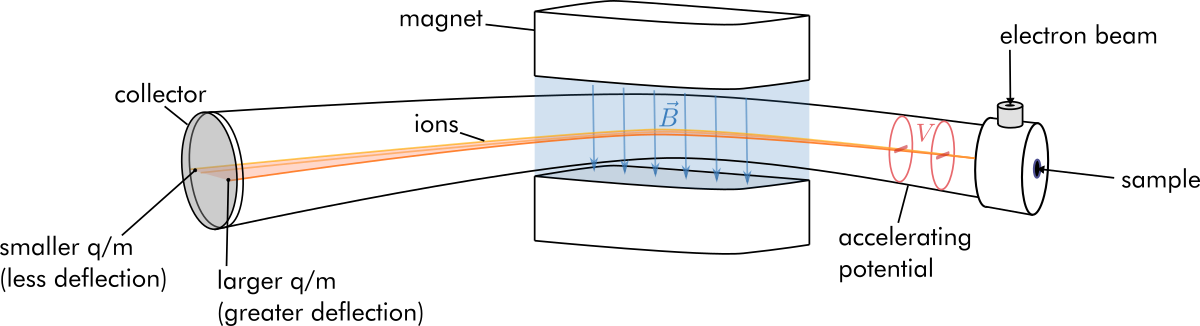

**Figure 4**. Mass spectrometer schematic.

The mass spectrometer functions as follows.

- At the entry point, the sample is ionized by an electron beam. 

- The ions are accelerated through an electrical potential. Only positive ions are accelerated (an electrode repels negative ions while neutral ions will not be accelerated). Most of the ions have a charge of z = +1 (the charge is denoted z in mass spec).

- The accelerated ions are passed through a magnet, causing them to deflect. 

- Ions arrive at the collector $-$ considering only ions with a charge of +1, lighter ions are deflected further than massive ions.

- The collector records the distribution of ion intensities along the collector. 

The same theory discussed in this lab is used to compute the charge to mass ratio for various positions along the collector.  Data from the mass spectrometer is typically plotted as the relative abundance of ions as a function of the mass to charge ratio, m/z.

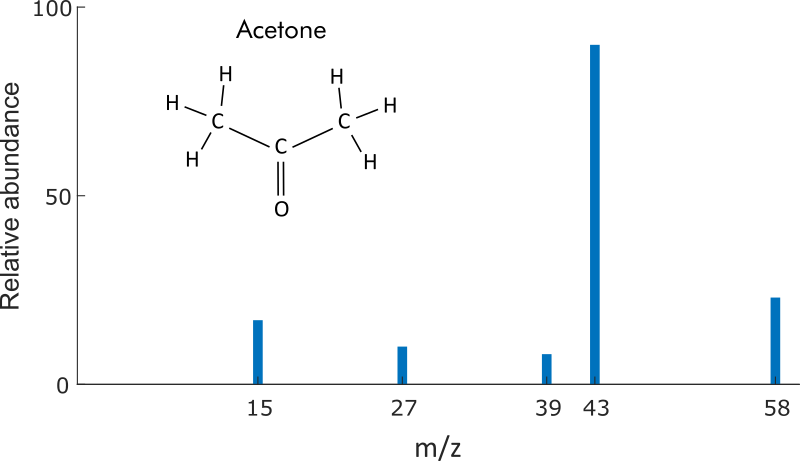

**Figure 5**. Simplified output of a mass spectrometer. The abundance is plotted against the mass to charge ratio, m/z. Here, the approximate values for the mass spectrum of acetone are shown.

**Example. **Propane mass spectrum

Propane is itself neutral, but when ionized, it can produce several derivative positively charged ions.

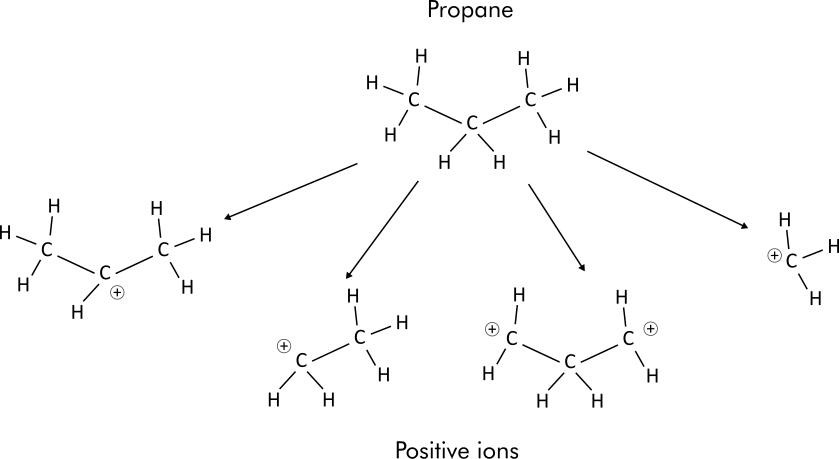

**Figure 6**. Propane and some positively charged derivative ions

The atomic weights of carbon and hydrogen are 12.011 and 1.008 [amu](https://en.wikipedia.org/wiki/Dalton_(unit)), respectively. You can use this information to compute the ions' mass to charge ratios, m/z. Note that this is the reciprocal of the charge to mass ratio, z/m.

mC = 12.011;
mH = 1.008;

% This computes the mass to charge ratios for the four ions pictured in Figure 6
mq =[ (3*mC + 7*mH)/1, (2*mC + 5*mH)/1, (3*mC + 6*mH)/2, (1*mC + 3*mH)/1]

Based on this calculation, you would expect that the mass spectrum will have peaks at 43, 29, 21, and 15. Visit the [NIST Chemistry WebBook](https://webbook.nist.gov/cgi/cbook.cgi?ID=C74986&Mask=200#Mass-Spec) to see the standard mass spectrum for propane and reflect on the following questions.

- Can you identify these ions in the mass spectrum? 

- Which ion is the most abundant?

- Can you derive any other ions that are visible in the mass spectrum but were not shown in **Fig. 6**?

- Why aren't negative ions shown?